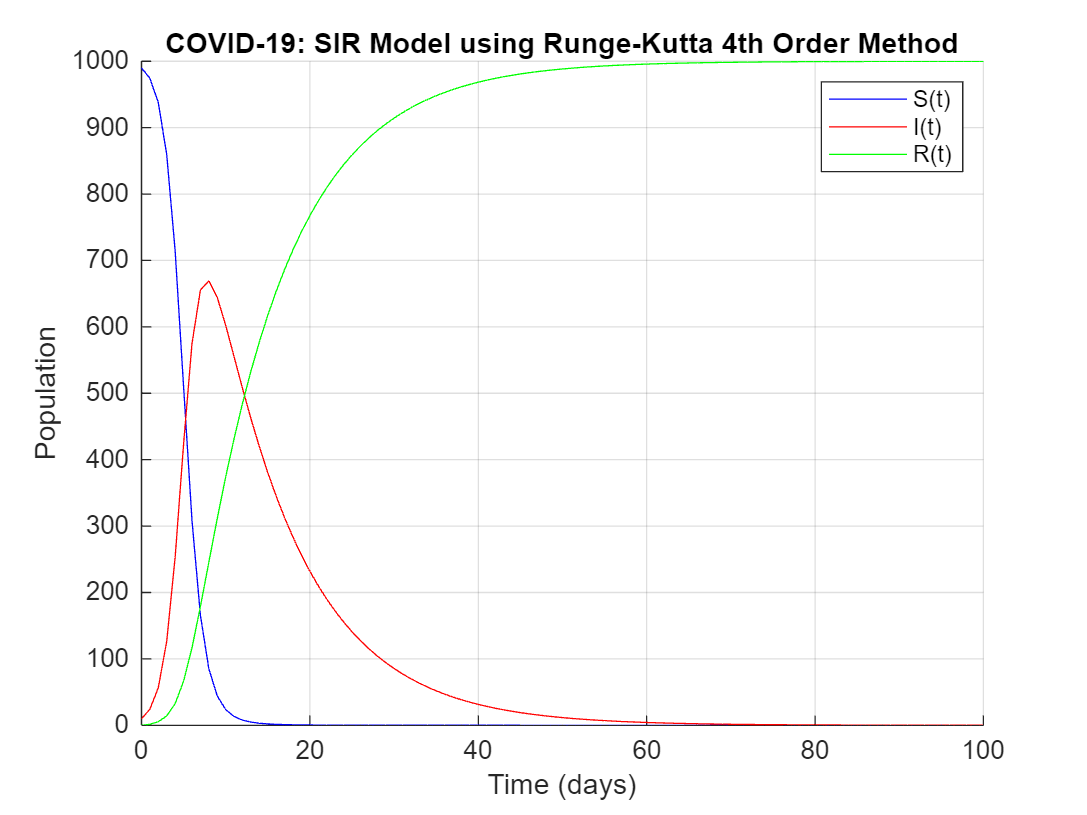

clear all

% Main script

% Parameters for Seasonal Influenza
beta_seasonal = 0.3;
gamma_seasonal = 0.1;

% Parameters for COVID-19
beta_covid = 1.0;
gamma_covid = 0.1;

% Parameters for Measles
beta_measles = 2;
gamma_measles = 0.2;

% Time settings
h = 1; % Time step (days)
t = 0:h:100; % Time vector

% Initial conditions
S0 = 990;
I0 = 10;
R0 = 0;
N = S0 + I0 + R0; % Total population

% Simulate for Seasonal Influenza
[S_seasonal, I_seasonal, R_seasonal] = runge_kutta_SIR(beta_seasonal, gamma_seasonal, S0, I0, R0, h, t, N);

% Simulate for COVID-19
[S_covid, I_covid, R_covid] = runge_kutta_SIR(beta_covid, gamma_covid, S0, I0, R0, h, t, N);

% Simulate for Measles
[S_measles, I_measles, R_measles] = runge_kutta_SIR(beta_measles, gamma_measles, S0, I0, R0, h, t, N);

% Plot results for Seasonal Influenza
figure;
hold on;
plot(t, S_seasonal, 'b-', 'DisplayName', 'S(t)');
plot(t, I_seasonal, 'r-', 'DisplayName', 'I(t)');
plot(t, R_seasonal, 'g-', 'DisplayName', 'R(t)');
xlabel('Time (days)');
ylabel('Population');
title('Seasonal Influenza: SIR Model using Runge-Kutta 4th Order Method');
legend;
grid on;
hold off;

% Plot results for COVID-19
figure;
hold on;
plot(t, S_covid, 'b-', 'DisplayName', 'S(t)');
plot(t, I_covid, 'r-', 'DisplayName', 'I(t)');
plot(t, R_covid, 'g-', 'DisplayName', 'R(t)');
xlabel('Time (days)');
ylabel('Population');
title('COVID-19: SIR Model using Runge-Kutta 4th Order Method');
legend;
grid on;
hold off;

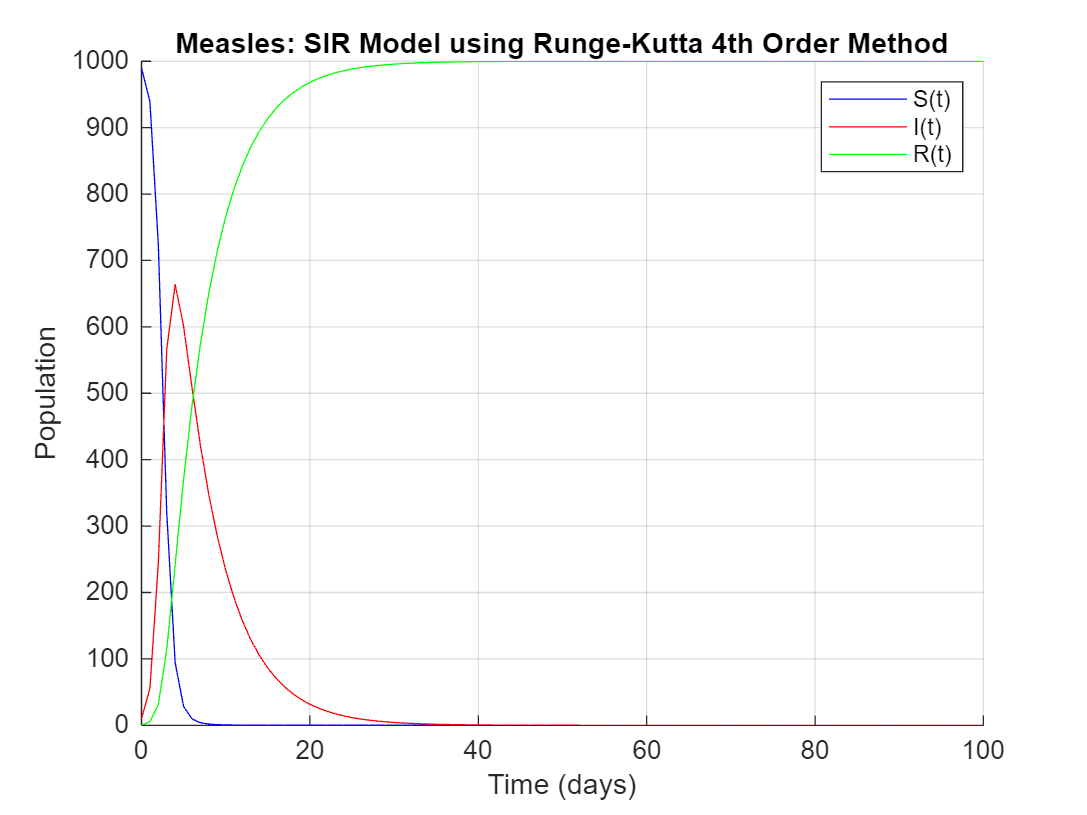


% Plot results for Measles
figure;
hold on;
plot(t, S_measles, 'b-', 'DisplayName', 'S(t)');
plot(t, I_measles, 'r-', 'DisplayName', 'I(t)');
plot(t, R_measles, 'g-', 'DisplayName', 'R(t)');
xlabel('Time (days)');
ylabel('Population');
title('Measles: SIR Model using Runge-Kutta 4th Order Method');
legend;
grid on;
hold off;

%% Part 2

n_lin=0; % Number of interpolated points
for i=1:101 %% Linear interpolation in Newton form
    if rem(t(i),2)==0 %% even days
        p2_S_lin(i)=S_seasonal(i);
        p2_I_lin(i)=I_seasonal(i);
        p2_R_lin(i)=R_seasonal(i);
    elseif i==1 %% initial condition
        p2_S_lin(i)=S0;
        p2_I_lin(i)=I0;
        p2_R_lin(i)=R0;
    else %% odd days
        p2_S_lin(i)=S_seasonal(i-1)+(S_seasonal(i+1)-S_seasonal(i-1))/(t(i+1)-t(i-1))*(t(i)-t(i-1));
         p2_I_lin(i)=I_seasonal(i-1)+(I_seasonal(i+1)-I_seasonal(i-1))/(t(i+1)-t(i-1))*(t(i)-t(i-1));
          p2_R_lin(i)=R_seasonal(i-1)+(R_seasonal(i+1)-R_seasonal(i-1))/(t(i+1)-t(i-1))*(t(i)-t(i-1));
          n_lin=n_lin+1;
    end
end

for i=1:101 % EL2 intermediate step
    err_S_lin(i)=(p2_S_lin(i)-S_seasonal(i))^2;
        err_I_lin(i)=(p2_I_lin(i)-I_seasonal(i))^2;
        err_R_lin(i)=(p2_R_lin(i)-R_seasonal(i))^2;  
end
    
EL2_S_sum_lin = sum(err_S_lin);
EL2_I_sum_lin=sum(err_I_lin);
EL2_R_sum_lin=sum(err_R_lin);
 EL2_S_lin=sqrt(EL2_S_sum_lin/n_lin); % EL2 for S(t)
  EL2_I_lin=sqrt(EL2_I_sum_lin/n_lin); % EL2 for I(t)
EL2_R_lin=sqrt(EL2_R_sum_lin/n_lin); % EL2 for R(t)

n_quad=0; % Number of interpolated points
for i=1:101 %% Quadratic interpolation in Newton form
    if rem(t(i),2)==0 %% even days
        p2_S_quad(i)=S_seasonal(i);
        p2_I_quad(i)=I_seasonal(i);
        p2_R_quad(i)=R_seasonal(i);
    elseif i==1 %% initial condition
        p2_S_quad(i)=S0;
        p2_I_quad(i)=I0;
        p2_R_quad(i)=R0;
    else %% odd days
        if i<99
        b0_S=S_seasonal(i-1);
        b1_S=(S_seasonal(i+1)-S_seasonal(i-1))/(t(i+1)-t(i-1));
        b2_S=((S_seasonal(i+3)-S_seasonal(i+1))/(t(i+3)-t(i+1))-b1_S)/(t(i+3)-t(i-1));
        % The above formula uses S_0, S_1, and S_2. S_2 is represented by
        % S(i+3) because S(i+2) is an odd day--thus this point is unknown. The
        % next known point is S(i+3).
        p2_S_quad(i)=b0_S+b1_S*(t(i)-t(i-1))+b2_S*(t(i)-t(i-1))*(t(i)-t(i+1));

        b0_I=I_seasonal(i-1);
        b1_I=(I_seasonal(i+1)-I_seasonal(i-1))/(t(i+1)-t(i-1));
        b2_I=((I_seasonal(i+3)-I_seasonal(i+1))/(t(i+3)-t(i+1))-b1_I)/(t(i+3)-t(i-1));
        p2_I_quad(i)=b0_I+b1_I*(t(i)-t(i-1))+b2_I*(t(i)-t(i-1))*(t(i)-t(i+1));

        b0_R=R_seasonal(i-1);
        b1_R=(R_seasonal(i+1)-R_seasonal(i-1))/(t(i+1)-t(i-1));
        b2_R=((R_seasonal(i+3)-R_seasonal(i+1))/(t(i+3)-t(i+1))-b1_R)/(t(i+3)-t(i-1));
        p2_R_quad(i)=b0_R+b1_R*(t(i)-t(i-1))+b2_R*(t(i)-t(i-1))*(t(i)-t(i+1));
        
        n_quad=n_quad+1;
        end
    end
end

for i=1:99 % EL2 intermediate step
    err_S_quad(i)=(p2_S_quad(i)-S_seasonal(i))^2;
    err_I_quad(i)=(p2_I_quad(i)-I_seasonal(i))^2;
    err_R_quad(i)=(p2_R_quad(i)-R_seasonal(i))^2;
end

EL2_S_sum_quad = sum(err_S_quad);
EL2_I_sum_quad=sum(err_I_quad);
EL2_R_sum_quad=sum(err_R_quad);
 EL2_S_quad=sqrt(EL2_S_sum_quad/n_quad); % EL2 for S(t)
  EL2_I_quad=sqrt(EL2_I_sum_quad/n_quad); % EL2 for I(t)
EL2_R_quad=sqrt(EL2_R_sum_quad/n_quad); % EL2 for R(t)
EL2= [EL2_S_lin EL2_I_lin EL2_R_lin; EL2_S_quad EL2_I_quad EL2_R_quad]

EL2 =     0.6491    0.5032    0.4112
    0.1046    0.0918    0.0506



% Quadratic interpolation provides data points with smaller errors.


% Function to perform Runge-Kutta 4th Order Method
function [S, I, R] = runge_kutta_SIR(beta, gamma, S0, I0, R0, h, t, N)
    % Initialize arrays
    S = zeros(1, length(t));
    I = zeros(1, length(t));
    R = zeros(1, length(t));
    S(1) = S0;
    I(1) = I0;
    R(1) = R0;

    for i = 1:(length(t) - 1)
        % Define ODE functions
        fS = @(S, I) -(beta/N) * S * I;
        fI = @(S, I) (beta/N) * S * I - gamma * I;
        fR = @(I) gamma * I;

        % Runge-Kutta 4th Order Method
        k1_S = fS(S(i), I(i));
        k1_I = fI(S(i), I(i));
        k1_R = fR(I(i));

        k2_S = fS(S(i) + 0.5 * k1_S * h, I(i) + 0.5 * k1_I * h);
        k2_I = fI(S(i) + 0.5 * k1_S * h, I(i) + 0.5 * k1_I * h);
        k2_R = fR(I(i) + 0.5 * k1_I * h);

        k3_S = fS(S(i) + 0.5 * k2_S * h, I(i) + 0.5 * k2_I * h);
        k3_I = fI(S(i) + 0.5 * k2_S * h, I(i) + 0.5 * k2_I * h);
        k3_R = fR(I(i) + 0.5 * k2_I * h);

        k4_S = fS(S(i) + k3_S * h, I(i) + k3_I * h);
        k4_I = fI(S(i) + k3_S * h, I(i) + k3_I * h);
        k4_R = fR(I(i) + k3_I * h);

        S(i+1) = S(i) + (1/6) * (k1_S + 2*k2_S + 2*k3_S + k4_S) * h;
        I(i+1) = I(i) + (1/6) * (k1_I + 2*k2_I + 2*k3_I + k4_I) * h;
        R(i+1) = R(i) + (1/6) * (k1_R + 2*k2_R + 2*k3_R + k4_R) * h;
    end
end

%the parameters show that measles is the most infectious disease as 2 is
%greater than 1. Also on the graph more people are infected within a
%shorter time period. Eventhought measles is the most infectious, people
%are more susceptible for a longer period of time with the seasonal flu. To
%add, measles has the higher number of recovery rates than the rest.
